# Крок 0: Очищення середовища

clear; clc; close all;

## Крок 1: Завантаження зображень

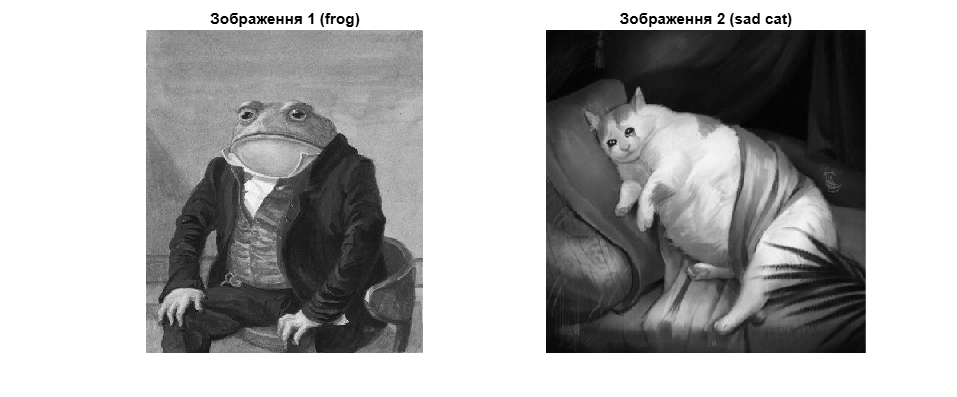

image1 = imread('images/frog.jpg');
image2 = imread('images/sad_cat.jpg');

if size(image1, 3) == 3
    image1 = rgb2gray(image1);
end
if size(image2, 3) == 3
    image2 = rgb2gray(image2);
end

image1 = im2double(image1);
image2 = im2double(image2);

figure('Name','Крок 1: Оригінальні зображення','NumberTitle','off');
subplot(1,2,1), imshow(image1), title('Зображення 1 (frog)');
subplot(1,2,2), imshow(image2), title('Зображення 2 (sad cat)');
truesize;

## Крок 2: Обчислення та відображення спектрів (без зсуву)

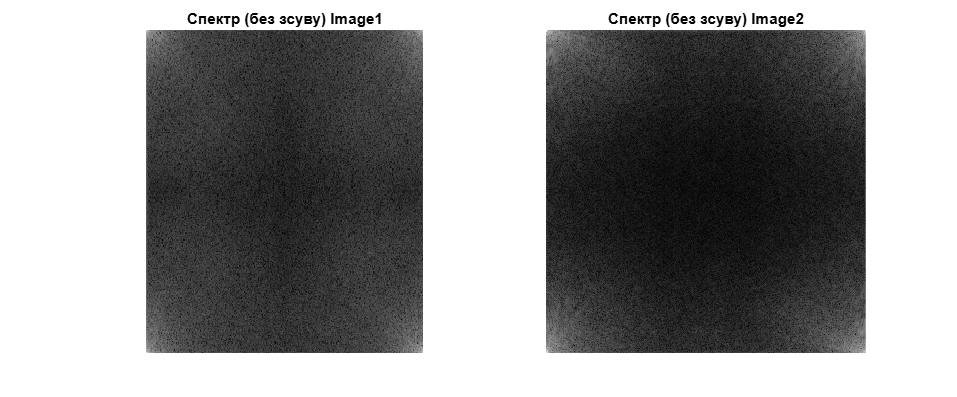

F1 = fft2(image1);
F2 = fft2(image2);

% Обчислюємо модуль (амплітуду) без зсуву
mag1_noShift = abs(F1);
mag2_noShift = abs(F2);

% Логарифмічна шкала для візуалізації
logMag1_noShift = log(1 + mag1_noShift);
logMag2_noShift = log(1 + mag2_noShift);

% Нормалізація та масштабування для відображення
normMag1_noShift = mat2gray(logMag1_noShift);
normMag2_noShift = mat2gray(logMag2_noShift);
scaledMag1_noShift = uint8(255 * normMag1_noShift);
scaledMag2_noShift = uint8(255 * normMag2_noShift);

figure('Name','Крок 2: Спектри без fftshift','NumberTitle','off');
subplot(1,2,1), imshow(scaledMag1_noShift, []), title('Спектр (без зсуву) Image1');
subplot(1,2,2), imshow(scaledMag2_noShift, []), title('Спектр (без зсуву) Image2');
truesize;

## Крок 3: Обчислення спектрів із застосуванням fftshift

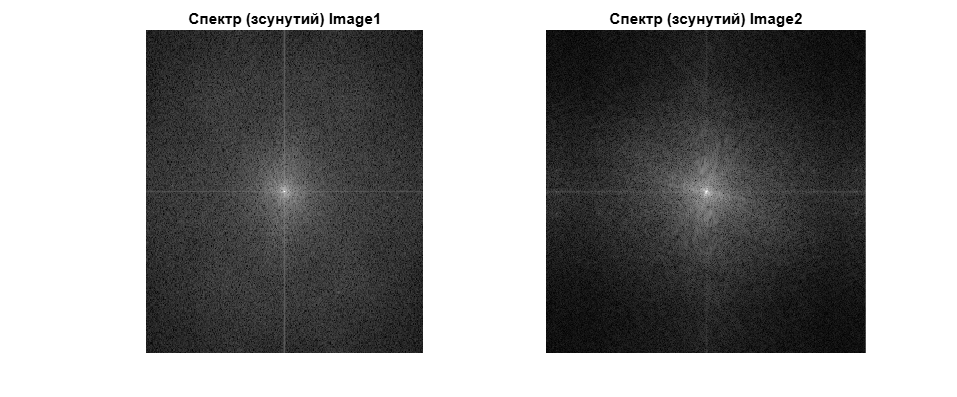

F1_shifted = fftshift(F1);
F2_shifted = fftshift(F2);

mag1_shifted = abs(F1_shifted);
mag2_shifted = abs(F2_shifted);

logMag1_shifted = log(1 + mag1_shifted);
logMag2_shifted = log(1 + mag2_shifted);

normMag1_shifted = mat2gray(logMag1_shifted);
normMag2_shifted = mat2gray(logMag2_shifted);
scaledMag1_shifted = uint8(255 * normMag1_shifted);
scaledMag2_shifted = uint8(255 * normMag2_shifted);

figure('Name','Крок 3: Спектри з fftshift','NumberTitle','off');
subplot(1,2,1), imshow(scaledMag1_shifted, []), title('Спектр (зсунутий) Image1');
subplot(1,2,2), imshow(scaledMag2_shifted, []), title('Спектр (зсунутий) Image2');
truesize;

## Крок 4: Відновлення зображень з амплітудного спектра

Відновлення зображення лише за модулем (фаза занулена)

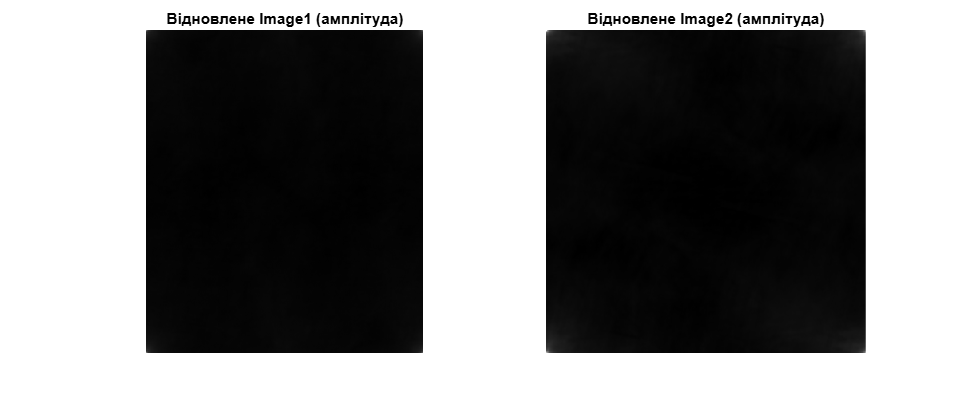

ampF1 = abs(F1);
ampF2 = abs(F2);

img1_restored_amp = ifft2(ampF1);
img2_restored_amp = ifft2(ampF2);

figure('Name','Крок 4: Відновлені зображення (амплітуда без фази)','NumberTitle','off');
subplot(1,2,1), imshow(abs(img1_restored_amp), []), title('Відновлене Image1 (амплітуда)');
subplot(1,2,2), imshow(abs(img2_restored_amp), []), title('Відновлене Image2 (амплітуда)');
truesize;

## Крок 5: Створення фільтрів Гауса та їх частотних характеристик

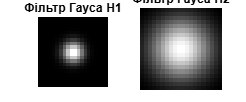

M = 20;  % розмір по вертикалі
N = 20;  % розмір по горизонталі
sigma1 = 2;
sigma2 = 5;

H1_small = fspecial('gaussian', [M N], sigma1);
H2_small = fspecial('gaussian', [M N], sigma2);

figure('Name','Крок 5: Фільтри Гауса (малі)','NumberTitle','off');
subplot(1,2,1), imshow(H1_small, []), title('Фільтр Гауса H1');
subplot(1,2,2), imshow(H2_small, []), title('Фільтр Гауса H2');
truesize;

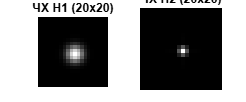


% Обчислюємо fft по їхньому розміру
H1_fft_small = fft2(H1_small);
H2_fft_small = fft2(H2_small);

figure('Name','Крок 5: Частотна характеристика малих фільтрів','NumberTitle','off');
subplot(1,2,1), imshow(abs(fftshift(H1_fft_small)), []), title('ЧХ H1 (20x20)');
subplot(1,2,2), imshow(abs(fftshift(H2_fft_small)), []), title('ЧХ H2 (20x20)');
truesize;

## Крок 6: Фільтрація зображень у частотній області

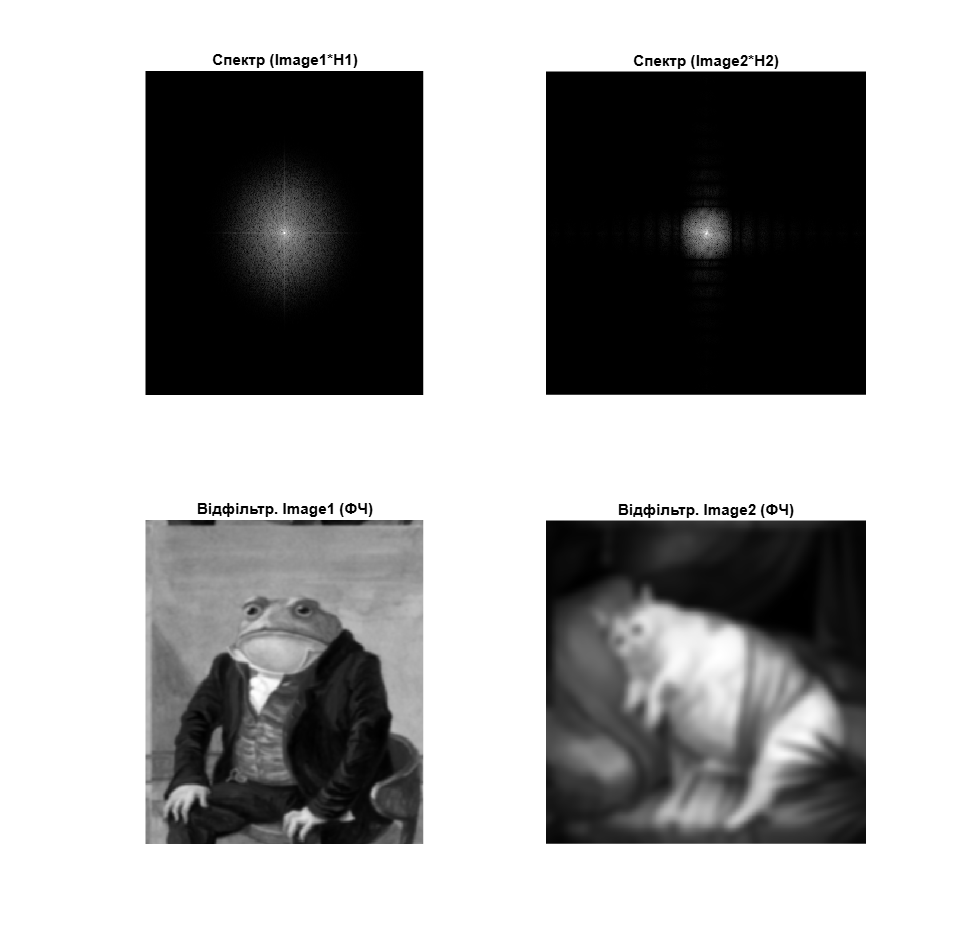

[rows1, cols1] = size(image1);
[rows2, cols2] = size(image2);

% FFT зображень з розмірами оригіналу
FFT_image1 = fft2(image1, rows1, cols1);
FFT_image2 = fft2(image2, rows2, cols2);

% FFT фільтрів з нульовим доповненням до розмірів зображень
FFT_filter1_forImage1 = fft2(H1_small, rows1, cols1);
FFT_filter2_forImage2 = fft2(H2_small, rows2, cols2);

% Перемноження в частотній області
product1 = FFT_image1 .* FFT_filter1_forImage1;
product2 = FFT_image2 .* FFT_filter2_forImage2;

% Зворотне перетворення
filteredImageFreq1 = ifft2(product1);
filteredImageFreq2 = ifft2(product2);

% Нормалізація для відображення
filteredImageFreq1_show = uint8(255*mat2gray(real(filteredImageFreq1)));
filteredImageFreq2_show = uint8(255*mat2gray(real(filteredImageFreq2)));

% Для візуалізації спектрів після фільтрації (логарифмічна шкала)
logSpec1 = mat2gray(log(1 + abs(fftshift(product1))));
logSpec2 = mat2gray(log(1 + abs(fftshift(product2))));

figure('Name','Крок 6: Фільтрація у частотній області','NumberTitle','off');
subplot(2,2,1), imshow(logSpec1, []), title('Спектр (Image1*H1)');
subplot(2,2,2), imshow(logSpec2, []), title('Спектр (Image2*H2)');
subplot(2,2,3), imshow(filteredImageFreq1_show, []), title('Відфільтр. Image1 (ФЧ)');
subplot(2,2,4), imshow(filteredImageFreq2_show, []), title('Відфільтр. Image2 (ФЧ)');
truesize;

## Крок 7: Фільтрація у просторі (просторова згортка)

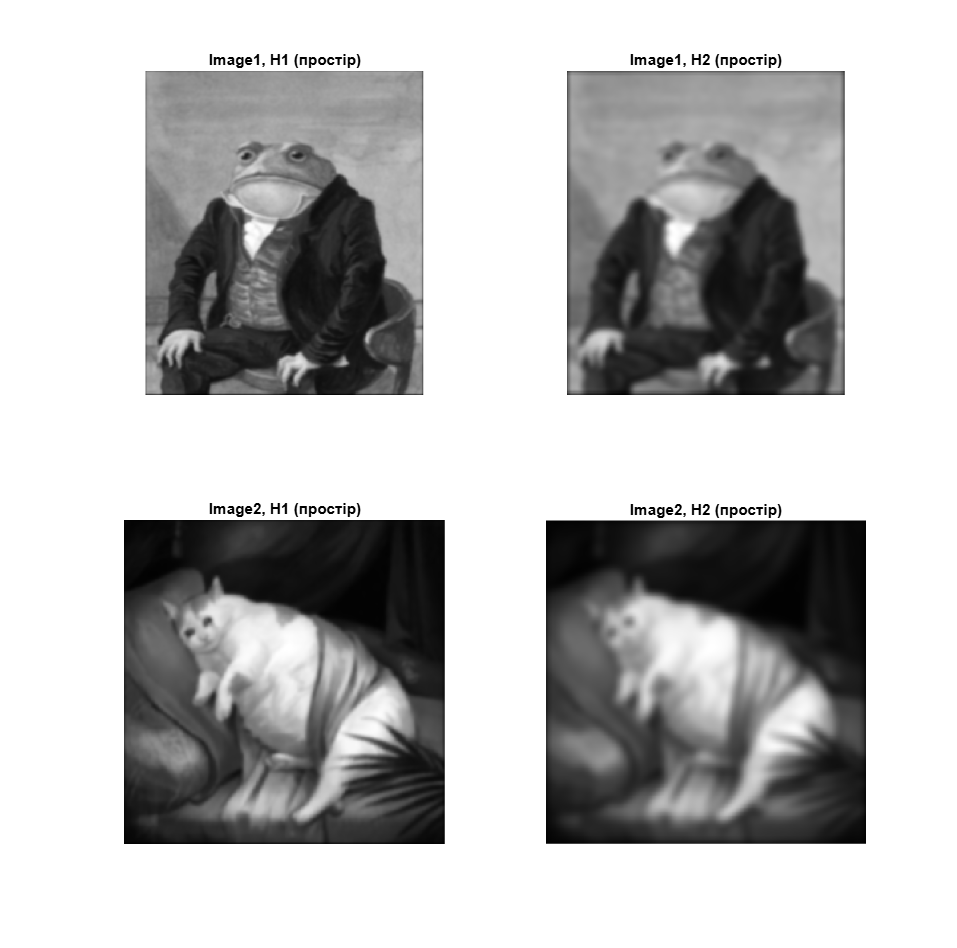

image1_spatial_H1 = imfilter(image1, H1_small, 'conv', 'same');
image1_spatial_H2 = imfilter(image1, H2_small, 'conv', 'same');
image2_spatial_H1 = imfilter(image2, H1_small, 'conv', 'same');
image2_spatial_H2 = imfilter(image2, H2_small, 'conv', 'same');

figure('Name','Крок 7: Фільтрація у просторі','NumberTitle','off');
subplot(2,2,1), imshow(image1_spatial_H1, []), title('Image1, H1 (простір)');
subplot(2,2,2), imshow(image1_spatial_H2, []), title('Image1, H2 (простір)');
subplot(2,2,3), imshow(image2_spatial_H1, []), title('Image2, H1 (простір)');
subplot(2,2,4), imshow(image2_spatial_H2, []), title('Image2, H2 (простір)');
truesize;

## Крок 8: Порівняння результатів для Image1 (частотна vs. просторовa фільтрація H1)

Обчислюємо різницю між відфільтрованими зображеннями

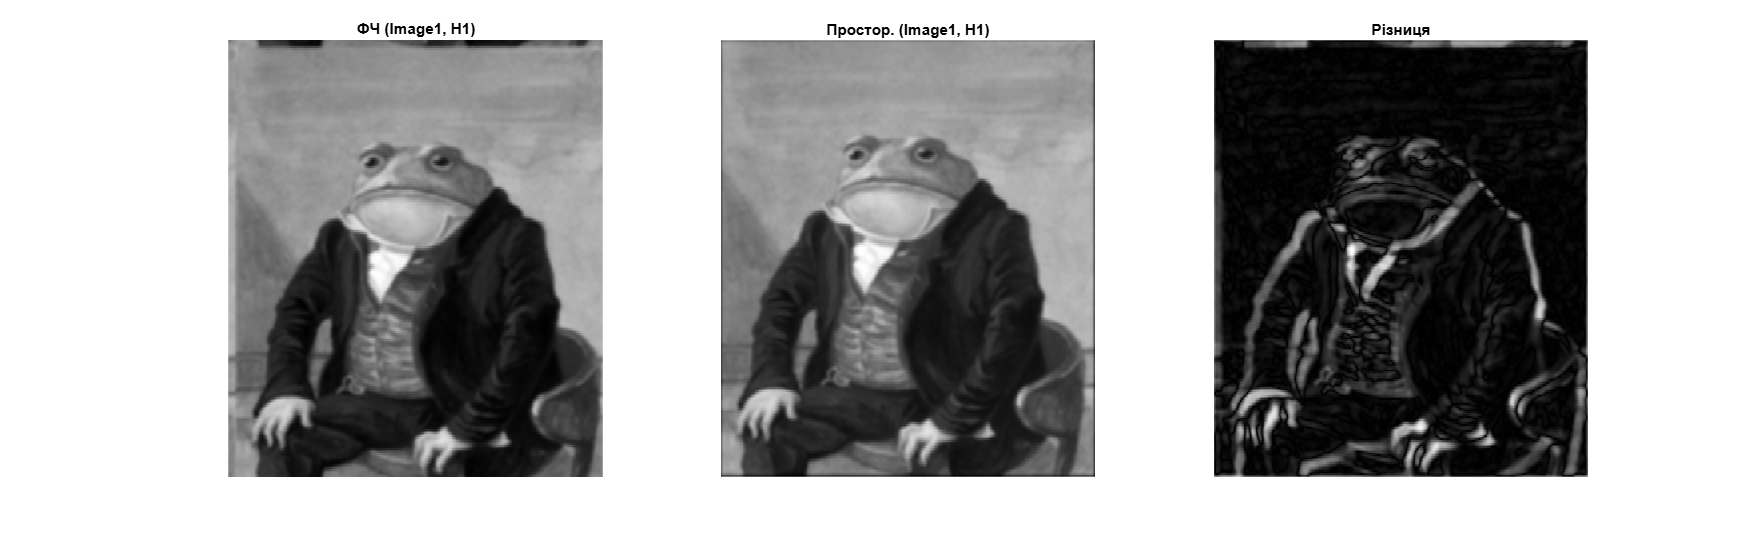

diffImage1_H1 = abs(filteredImageFreq1 - image1_spatial_H1);

figure('Name','Крок 8: Порівняння для Image1 (H1)','NumberTitle','off');
subplot(1,3,1), imshow(filteredImageFreq1_show, []), title('ФЧ (Image1, H1)');
subplot(1,3,2), imshow(image1_spatial_H1, []), title('Простор. (Image1, H1)');
subplot(1,3,3), imshow(mat2gray(diffImage1_H1), []), title('Різниця');
truesize;

## Крок 9: Додаткове порівняння для Image2 (частотна vs. просторовa фільтрація H2)

Обчислюємо різницю між відфільтрованими зображеннями

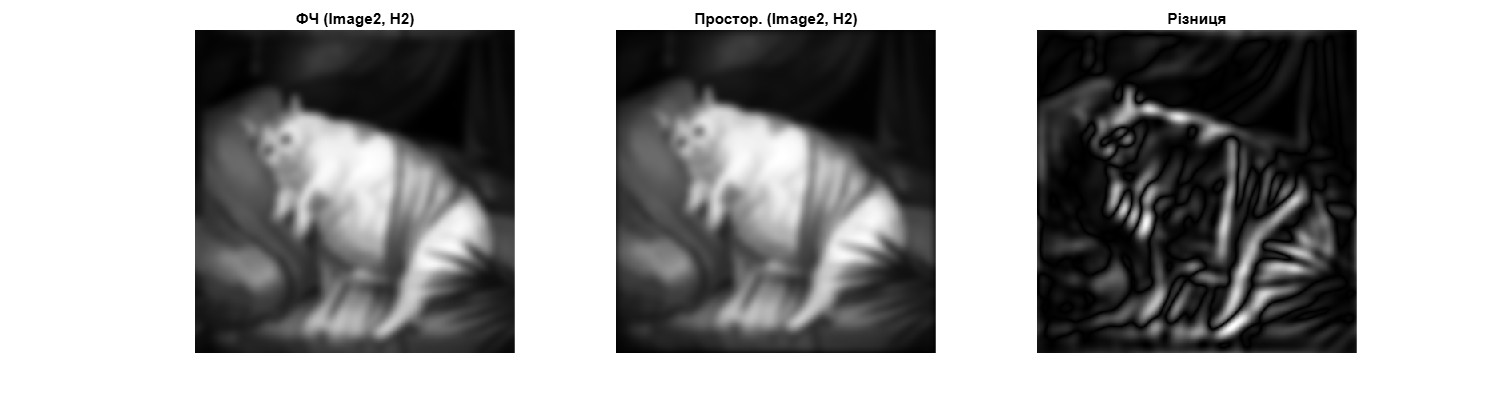

diffImage2_H2 = abs(filteredImageFreq2 - image2_spatial_H2);

figure('Name','Крок 9: Порівняння для Image2 (H2)','NumberTitle','off');
subplot(1,3,1), imshow(filteredImageFreq2_show, []), title('ФЧ (Image2, H2)');
subplot(1,3,2), imshow(image2_spatial_H2, []), title('Простор. (Image2, H2)');
subplot(1,3,3), imshow(mat2gray(diffImage2_H2), []), title('Різниця');
truesize;